Results Analysis / Post-Processing of NGSPICE Simulation of DSM

% load sim data
load clocks.mat
load dsm_nodes.mat


% transient sim results
N = length(v_dsm_op);
time = linspace(0, 1010e-6, N);
id = v_dsm_ip - v_dsm_in;
o1d = v_dsm_op1 - v_dsm_on1;
o2d = v_dsm_op2 - v_dsm_on2;
op = v_dsm_op;
op_avg = movmean(v_dsm_op, round(N/20));


Spectral Analysis

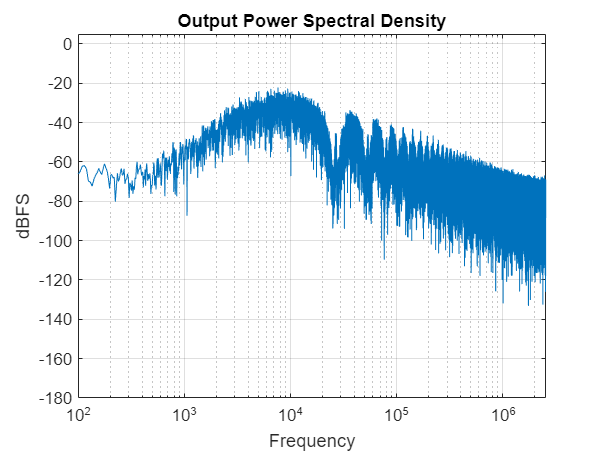

v_dsm_op_spec = v_dsm_op;
v_dsm_op_spec(v_dsm_op_spec < 0.9) = 0;
v_dsm_op_spec(v_dsm_op_spec > 0.9) = 1.8;

OSR = 512;
f_sampling = 5.12e6;
N = length(v_dsm_op_spec);
fft_bins = ceil(N/(2*OSR));
spec = fft(v_dsm_op_spec.*ds_hann(N));
psd_dbfs = 10*log10(abs(spec/(N/4)).^2);

figure;
semilogx(linspace(0, f_sampling/2, N/2+1), psd_dbfs(1:N/2+1));  
title("Output Power Spectral Density");
axis([1e2 f_sampling/2 -180 5])
xlabel("Frequency");
ylabel("dBFS"); 
grid;

Extract digital data for RTL run

% open file
fid = fopen('mod_out_ngspice.txt', 'w');
t_idx = 4900;  % initial valid time index
while(round(t_idx) < 984456)
    val = round(v_dsm_op_spec(round(t_idx)))/2;
    if(val ~= 1 && val ~= 0)
        disp("Error")
    end
    fprintf(fid, '%d\n', val);
    t_idx = t_idx + 195.3125e-9/1010e-6*984456;
end
fclose(fid);


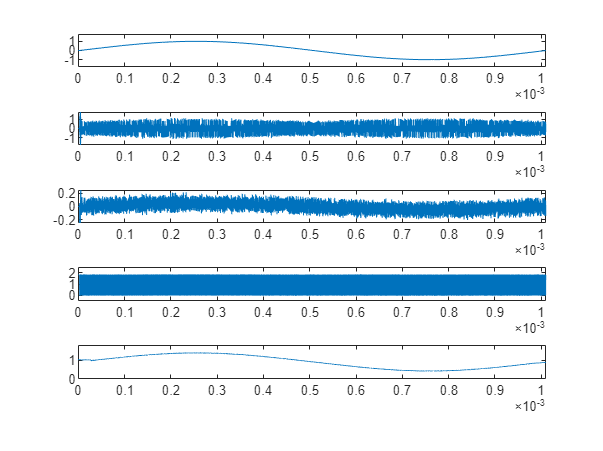

% Plotting
figure;
subplot(5,1,1);
plot(time,id)
axis([0 1010e-6 -1.8 1.8])
% title("Differential Input")

subplot(5,1,2);
plot(time,o1d);
axis([0 1010e-6 -1.8 1.8])
% title("Int 1 Output")

subplot(5,1,3);
plot(time,o2d);
axis([0 1010e-6 -0.25 0.25])
% title("Int 2 Output")

subplot(5,1,4);
plot(time, op);
axis([0 1010e-6 -0.5 2.5])
% title("Mod Output")

subplot(5,1,5);
plot(time,op_avg);
axis([0 1010e-6 0 1.8])

% title("Moving Average Filtered Mod Output")


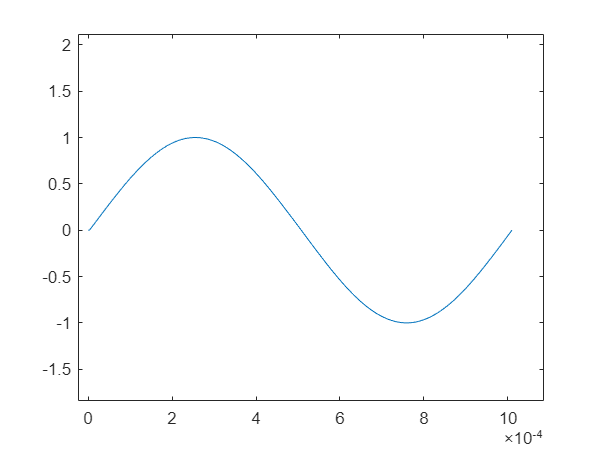

figure;
plot(time/1e-3,id)
axis([0 1010e-3 -1.8 1.8])

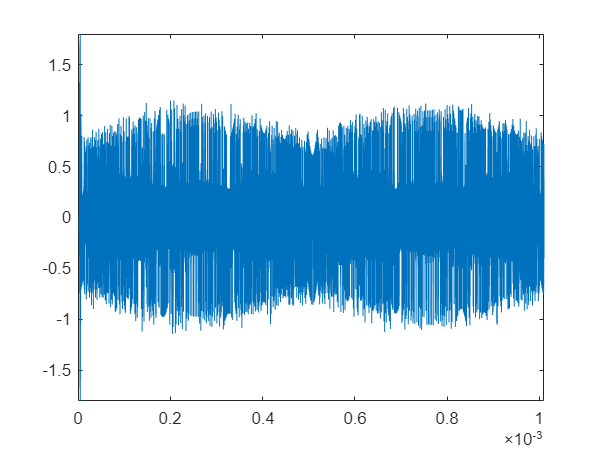

xlabel("Time (ms)")
ylabel("(V)")
title("Differential Input")

figure;
plot(time/1e-3,o1d);
axis([0 1010e-3 -1.8 1.8])

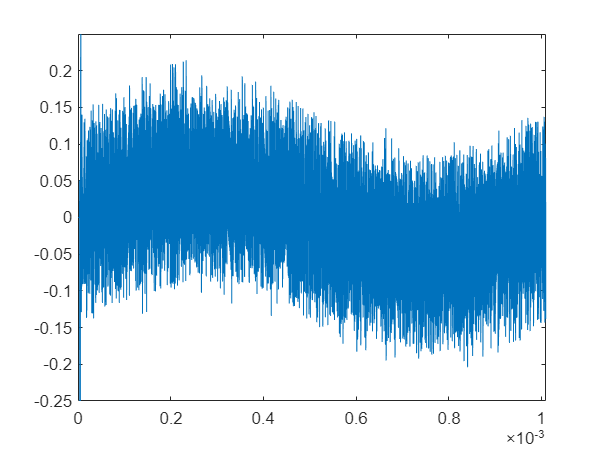

xlabel("Time (ms)")
ylabel("(V)")
title("Differential Integrator 1 Output")

figure;
plot(time/1e-3,o2d);
axis([0 1010e-3 -0.25 0.25])

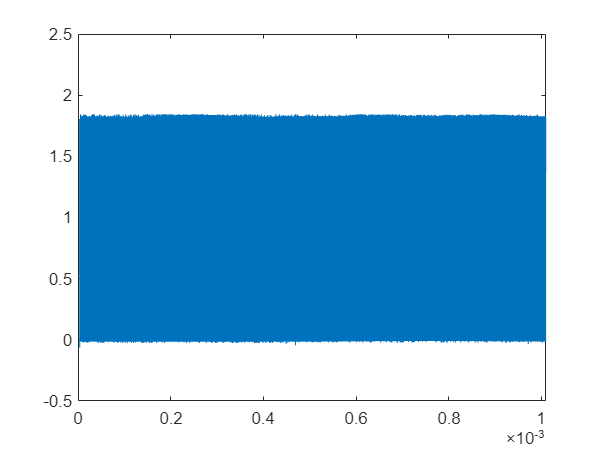

xlabel("Time (ms)")
ylabel("(V)")
title("Differential Integrator 2 Output")

figure;
plot(time/1e-3, op);
axis([0 1010e-3 -0.5 2.3])

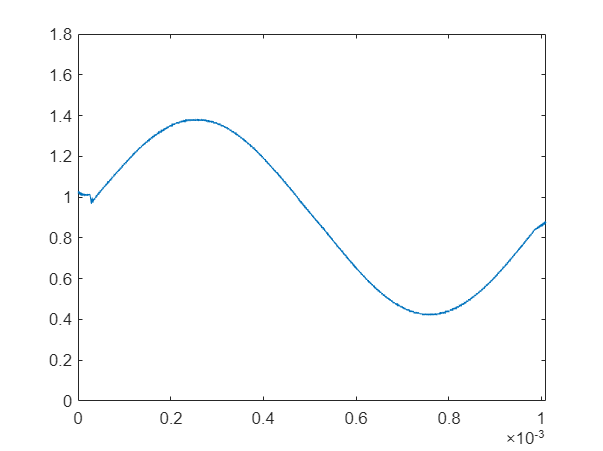

xlabel("Time (ms)")
ylabel("(V)")
title("Modulator Positive Output")

figure;
plot(time/1e-3,op_avg);
axis([0 1010e-3 0 1.8])

xlabel("Time (ms)")
ylabel("(V)")
title("Simulated Post-Filter Output")